**Experiment - 1                                                                   Date :- 12 / 1 /24**

**Aim :- Introduction to MATLAB and generate various discrete - time signals**

**Lab Exercise**

A) For a given M x M matrix denoted matrix with variable X , count the occurence of a given number N

clc ; clear all ; close all ;

M = 5 ; X = randi(20,M,M) ; ctr = 0 ; N = 10 ;

for i = 1:M
    for j = 1:M
        if (X(i,j) == N)
            ctr = ctr + 1 ;
        end
    end
end

disp(X) ; fprintf("No. of times :- %d",ctr) ;

     4    19     4    18     1
     5     3    12     2    18
    19    15     6     5     4
    14    15     3     2     2
    10    12     5     9     7

No. of times :- 1

B) Generate discrete unit step , unit impulse , unit ramp signals and plot the same 

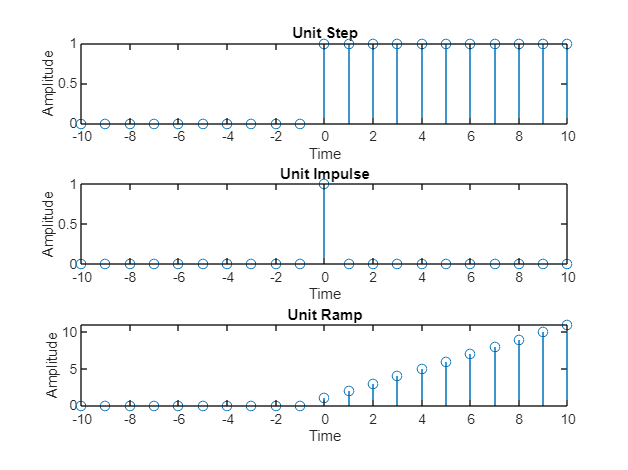

clc ; clear all ; close all ;

% Unit Step
N = 10 ; y1 = [zeros(1,2*N + 1)] ;
for i = 1:(2*N + 1)
    if (i <= N)
        y1(i) = 0 ;
    end
    if (i > N)
        y1(i) = 1 ;
    end
end
subplot(3,1,1) ; stem(-N:N , y1) ; ylabel("Amplitude") ; xlabel("Time") ; title("Unit Step") ;

%Unit Impulse
y2 = [zeros(1,2*N + 1)] ;
for i = 1:(2*N + 1)
    if (i == N + 1)
        y2(i) = 1 ;
    end
end
subplot(3,1,2) ; stem(-N:N , y2) ; ylabel("Amplitude") ; xlabel("Time") ; title("Unit Impulse") ;

%Unit Ramp
y3 = [zeros(1,2*N + 1)] ;
for i = 1:(2*N + 1)
    if (i <= N)
        y3(i) = 0 ;
    end
    if (i > N)
        y3(i) = i - N ;
    end
end
subplot(3,1,3) ; stem(-N:N , y3) ; ylabel("Amplitude") ; xlabel("Time") ; title("Unit Ramp") ;

C) Generate a sine wave of 100Hz , sampled at 8KHz for a duration of 20ms . Repeat the experiment for different sampling rates like 100Hz, 200Hz, 500Hz and 1KHz and comment on the results 

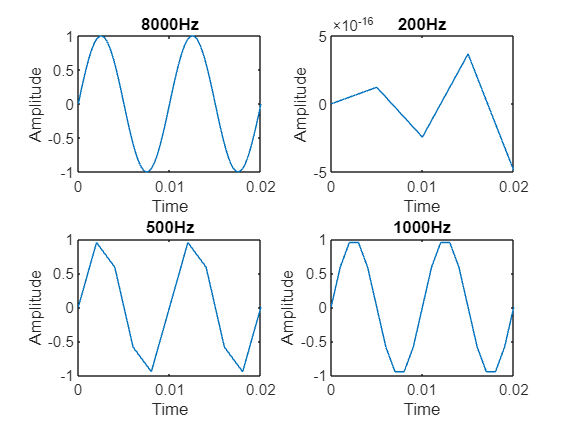

clc ; clear all ; close all ;
%8000Hz
freq = 100 ; samp1 = 8000 ; dur = 0.02 ;

t1 = 0 : (1/samp1) : dur ;
x1 = sin(2*pi*freq*t1) ;
subplot(2,2,1) ; plot(t1,x1) ; xlabel("Time") ; ylabel("Amplitude") ; title("8000Hz") ;
soundsc(x1 , samp1)

%200Hz
samp2 = 200 ;
t2 = 0 : (1/samp2) : dur ;
x2 = sin(2*pi*freq*t2) ;
subplot(2,2,2) ; plot(t2,x2) ; xlabel("Time") ; ylabel("Amplitude") ; title("200Hz") ;

%500Hz
samp3 = 500 ;
t3 = 0 : (1/samp3) : dur ;
x3 = sin(2*pi*freq*t3) ;
subplot(2,2,3) ; plot(t3,x3) ; xlabel("Time") ; ylabel("Amplitude") ; title("500Hz") ;

%1KHz
samp4 = 1000 ;
t4 = 0 : (1/samp4) : dur ;
x4 = sin(2*pi*freq*t4) ;
subplot(2,2,4) ; plot(t4,x4) ; xlabel("Time") ; ylabel("Amplitude") ; title("1000Hz") ;

Comments :- Here , we do not get a curve similar to sin wave in 100Hz and 200Hz because MATLAB does not use any interpolation between two dots . It just connects two dots with a straight line .

D) Generate a signal which is represented as sum of the following sinusoids :

    x1(t) = 5cos(2pi500t),

    x2(t) = 5cos(2pi1200t + 0.25pi),

    x3(t) = 5cos(2pi1800t + 0.5pi)

Hint : Choose an appropriate sampling rate for generating a signal

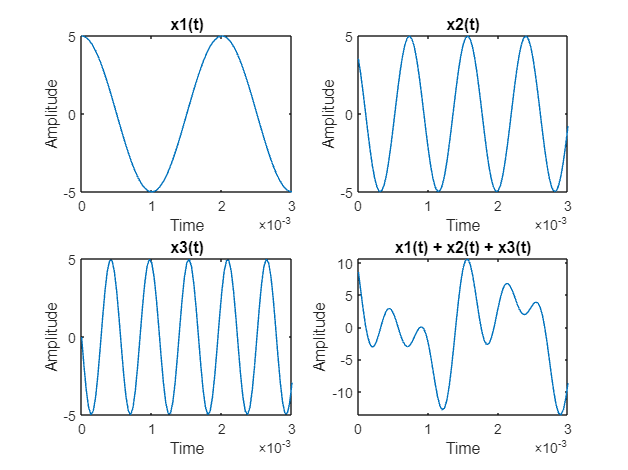

clc ; clear all ; close all ;

%x1(t)
freq1 = 500 ; samp = 30000 ; dur = 0.003 ;

t = 0 : (1/samp) : dur ;
x1 = 5 * cos(2*pi*freq1*t) ;
subplot(2,2,1) ; plot(t,x1) ; xlabel("Time") ; ylabel("Amplitude") ; title("x1(t)") ;

%x2(t)
freq2 = 1200 ;

x2 = 5 * cos(2*pi*freq2*t + 0.25*pi) ;
subplot(2,2,2) ; plot(t,x2) ; xlabel("Time") ; ylabel("Amplitude") ; title("x2(t)") ;

%x3(t)
freq3 = 1800 ;

x3 = 5 * cos(2*pi*freq3*t + 0.5*pi) ;  
subplot(2,2,3) ; plot(t,x3) ; xlabel("Time") ; ylabel("Amplitude") ; title("x3(t)") ;

%x4(t)

x4 = x1 + x2 + x3 ;
subplot(2,2,4) ; plot(t,x4) ; xlabel("Time") ; ylabel("Amplitude") ; title("x1(t) + x2(t) + x3(t)") ;

**Conclusion :- **1) Learning basics of Matlab .

                        2) Generated differect basic signals like Unit Step , Unit Ramp and Unit Impulse using FOR loops .

                        3) Generated different waves at different sampling frequencies and learnt about interpolation and we got to know that Matlab does not use any interpolation .

                        4) Generated different signals and and observed the sum of all individual signals at the same sampling frequency . Also , we tried and tested the output at different sampling frequencies .

**Thank You !**